# Chapter 4, Section 2 (Part 1)

The goal of this activity is to introduce what is known as the **null space** and **range** of a linear transformation.

# The Nullspace

**Definition:** Let $V$ and $W$ be vector spaces and $T: V\rightarrow W$ a linear transformation. The **null space ** of $T$, denoted by $N(T)$, is defined by


$$N(T)=\left\{\vec v\in V:\ T(\vec v)=\vec 0\right\}$$


Here's an image showing the two vector spaces $V$ and $W$.

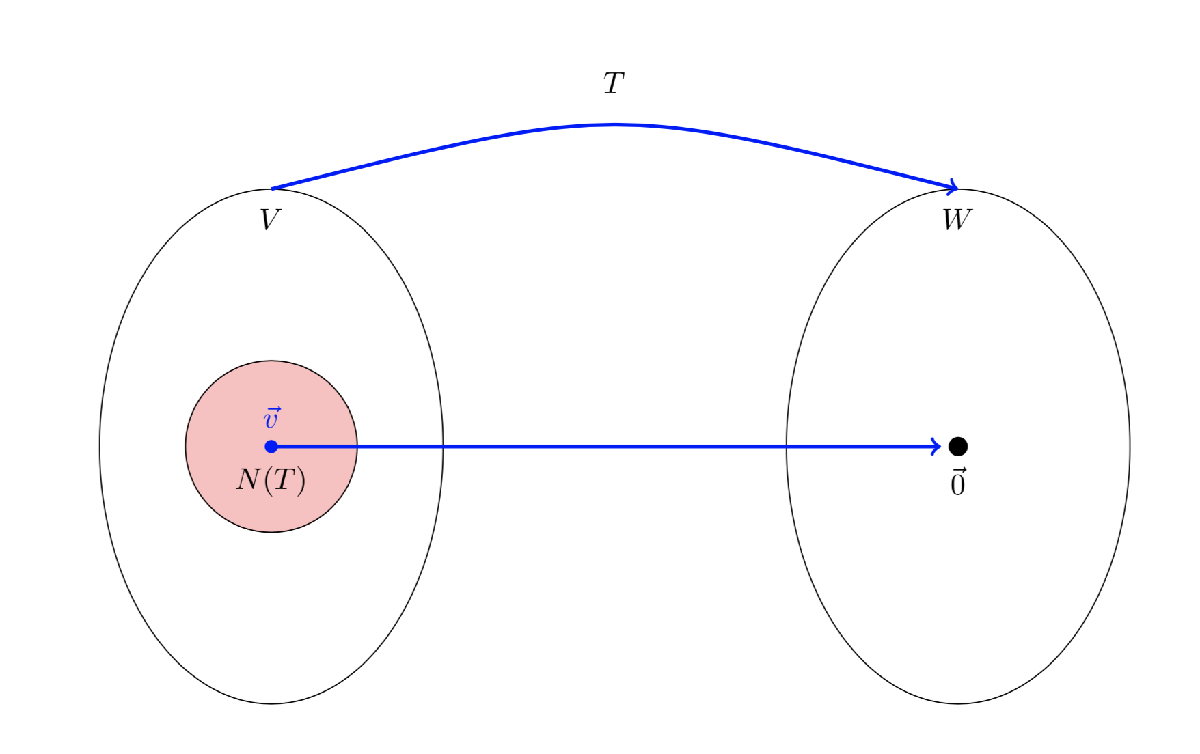

Note that the null space is a collection of all vectors in $V$, shaded in pink, that are mapped to the zero vector in $W$ by transformation $T$. 

# **Theorem 1**

The null space of $T$ is a subspace of $V$.

**Proof:** We need to show two things.

- $N(T)$ is closed under vector addition.

- $N(T)$ is closed under scalar multiplication.

**Part 1:** Let $\vec u, \vec v\in N(T)=\left\{\vec v\in V:\ T(\vec v)=\vec 0\right\}$. This means that $T(\vec u)=\vec 0$ and $T(\vec v)=\vec 0$. Because $\vec u$ and $\vec v$ are in the vector space $V$, we know that the vector $\vec u+\vec v$ is also in the vector space $V$, but now we have to show that it is also in $N(T)$.


$$\begin{array}{rcl}
T(\vec u+\vec v)&=&T)(\vec u)+T(\vec v)\\
&=&\vec 0+\vec 0\\
&=&\vec 0
\end{array}$$


Because $T(\vec u+\vec v)=\vec 0$, this means that $\vec u+\vec v\in N(T)$, so we've shown that $N(T)$ is closed under vector addition.

**Part 2: ** Let $\vec u\in V$ and $c\in \mathbb R$. This means that $T(\vec u)=\vec 0$. Because $V$ is a vector space, we know that $c\vec u\in V$, but we need to show that $c\vec u\in N(T)$.


$$\begin{array}{rcl}
T(c\vec u)&=&c\, T(\vec u)\\
&=&c\, \vec 0\\
&=&\vec 0
\end{array}$$


Because $T(c\vec u)=\vec 0$, this means that $c\,\vec u\in N(T)$, so we've shown that $N(T)$ is closed under scalar multiplication.

Because we've proven both parts #1 and #2, we've shown that $N(T)$ is a subspace of the vector space $V$.

# Example #1

Given the matrix 


$$A=\pmatrix{1 & 0 & 2 & 1\cr 2 & 1 & 5 & 5\cr 0 & 1 & 1 & 3}$$


define $T: \mathbb R^4\rightarrow \mathbb R^3$ by $T(\vec x)=A\vec x$. Find a basis for the null space of $T$ (also known as the null space of $A$).

**Solution:** Because $N(T)=\left\{\vec x:\ T(\vec x)=0\right\}$, we need to solve $T(\vec x)=\vec 0$, or equivalently, $A\vec x=\vec 0$.


$$\begin{array}{rcl}
A\vec x&=&\vec 0\\
\pmatrix{1 & 0 & 2 & 1\cr 2 & 1 & 5 & 5\cr 0 & 1 & 1 & 3}\pmatrix{x_1\cr x_2\cr x_3\cr x_4}&=&\pmatrix{0\cr 0\cr 0\cr 0}
\end{array}$$


Set up the augmented matrix and row reduce.


$$\pmatrix{1 & 0 & 2 & 1 & 0\cr 2 & 1 & 5 & 5 & 0\cr 0 & 1 & 1 & 3 & 0}\ \matrix{~\cr R_2-2R_1\cr ~}\quad\longrightarrow\quad\pmatrix{ 1 & 0 & 2 & 1 & 0\cr 0 & 1 & 1 & 3 & 0\cr 0 & 1 & 1 & 3 & 0}\ \matrix{~\cr ~\cr R_3-R_2}\quad\longrightarrow\quad\pmatrix{1 & 0 & 2 & 1 & 0\cr 0 & 1 & 1 & 3& 0\cr 0 & 0 & 0 & 0 & 0}$$


We can check this with Matlab. We'll enter A, then add a column of zeros in the last column.

A=[1 0 2 1;2 1 5 5;0 1 1 3];
M=[A,zeros(3,1)]

M =      1     0     2     1     0
     2     1     5     5     0
     0     1     1     3     0


Now we will row reduce.

RM=rref(M)

RM =      1     0     2     1     0
     0     1     1     3     0
     0     0     0     0     0


Same answer.  Thus, we have two pivot variables $x_1$ and $x_2$, and two free variables $x_3$ and $x_4$. 


$$\begin{array}{rcl}
x_1+2x_3+x_4&=&0\\
x_2+x_3+3x_4&=&0\\
x_3&=&\text{free}\\
x_4&=&\text{free}
\end{array}$$


Using back substitution, we solve for the pivot variables in terms of the free variables.


$$\begin{array}{rcl}
x_1&=&-2x_3-x_4\\
x_2&=&-x_3-3x_4\\
x_3&=&x_3\\
x_4&=&x_4
\end{array}$$


Therefore, all solutions of $A\vec x=\vec 0$ can be written as:


$$\begin{array}{rcl}
\vec x&=&\pmatrix{x_1\cr x_2\cr x_3\cr x_4}\\
&=&\pmatrix{-2x_3-x_4\cr -x_3-3x_4\cr x_3\cr x_4}\\
&=&\pmatrix{-2x_3\cr -x_3\cr x_3\cr 0}+\pmatrix{-x_4\cr -3x_4\cr 0\cr x_4}\\
&=&x_3\pmatrix{-2\cr -1\cr 1\cr 0}+x_4\pmatrix{-1\cr -3\cr 0\cr 1}
\end{array}$$


Thus, any solution of $A\vec x=\vec 0$ can be written as a linear combination of these two vectors, so they span the nullspace of $N(T)$ (also written as $N(A)$). Moreover, they are linearly independent (since neither is a constant multiple of the other). Therefore, a basis for the nullspace $N(T)$ is:


$$B=\left\{\pmatrix{-2\cr -1\cr 1\cr 0},\ \pmatrix{-1\cr -3\cr 0\cr 1}\right\}$$


Let's check this with Matlab. Remember, bases are not unique, so Matlab might send us a different basis.

NA=null(A)

NA =     0.5361   -0.6666
   -0.6220   -0.6832
   -0.4461    0.2633
    0.3560    0.1400


This is a numerical result. Each of these vectors has length one.

n1=NA(:,1);
norm(n1)

ans = 1.0000

n2=NA(:,2);
norm(n2)

ans = 1.0000

And they are what is know as **orthogonal vectors** (their dot product is zero).

dot(n1,n2)

ans = 6.9389e-17

Note that 6.9389e-17 means $6.9389\times 10^{-17}$, which is essential zero. We might prefer the following use of the null command.

NA=null(A,'r')

NA =     -2    -1
    -1    -3
     1     0
     0     1


These are the same as our hand-calculated vectors. 

# A Faster Way

Now we will show a much faster way to find the basis for the nullspace. Recall that we have two pivot columns (columns one and two) and two free columns (columns three an four). Let's highlight column three. 


$$\pmatrix{1 & 0 & [2] & 1\cr 0 & 1 & [1] & 3\cr 0 & 0 & [0] & 0}$$


Note that column three is 2 times column one, plus 1 times column two. Hence, this means that


$$-2\pmatrix{1\cr 0\cr 0}-3\pmatrix{0\cr 1\cr 0}+1\pmatrix{2\cr 1\cr 0}+0\pmatrix{1\cr 3\cr 0}=\pmatrix{0\cr 0\cr 0}$$


so $\pmatrix{-2\cr -3\cr 1\cr 0}$ is a solution of $A\vec x=\vec 0$. Next, we'll highlight column four.


$$\pmatrix{1 & 0 & 2 & [1]\cr 0 & 1 & 1 & [3]\cr 0 & 0 & 0 & [0]}$$


Note that column four is 1 times column 1, plus 3 times column two. Hence, this means that


$$-1\pmatrix{1\cr 0\cr 0}-3\pmatrix{0\cr 1\cr 0}+0\pmatrix{2\cr 1\cr 0}+1\pmatrix{1\cr 3\cr 0}=\pmatrix{0\cr 0\cr 0}$$


so $\pmatrix{-1\cr -3\cr 0\cr 1}$ is a solution of $A\vec x=\vec 0$. It might seem that we are doing a significant amount of work here, but all of these steps can happen mentally without writing anything down, immediately giving us the basis 


$$B=\left\{\pmatrix{-2\cr -1\cr 1\cr 0},\ \pmatrix{-1\cr -3\cr 0\cr 1}\right\}$$


Because there are two vectors in this subspace, the dimension of the nullspace is $\text{dim}(N(T))=2$, which can also be written as $\text{dim}(N(A))=2$.

# The Range

**Definition:** Let $V$ and $W$ be vector spaces and $T: V\rightarrow W$ a linear transformation. The **range **of $T$, denoted by $R(T)$, is defined by


$$R(T)=\left\{T(\vec v):\ \vec v\in V\right\}$$


Here's an image showing the two vector spaces $V$ and $W$.

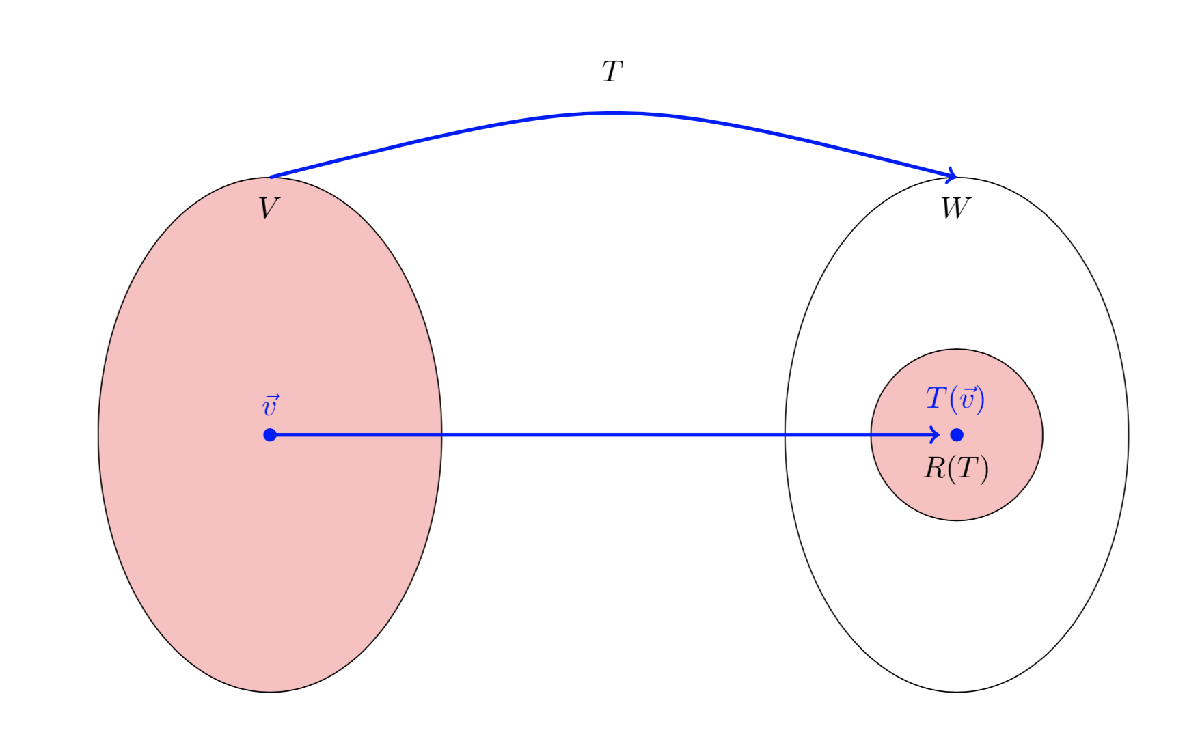

Note that the range is a collection of vectors $T(\vec v)$ in $W$, shaded in pink, that are mapped from vectors $\vec v\in V$ by the linear transformation $T$. 

# Theorem 2

The range of $T$ is a subspace of $W$.

**Proof:** We need to show two things.

- $R(T)$ is closed under vector addition.

- $R(T)$ is closed under scalar multiplication.

**Part 1:** Let $T(\vec u), \ T(\vec v)\in R(T)$. We have to show that $T(\vec u)+T(\vec v)\in R(T)$. Because $T(\vec u),\ T(\vec v)\in R(T)=\{T(\vec v):\ \vec v\in V\}$, this means that $\vec u,\ \vec v\in V$. Because $V$ is a vector space, it is closed under vector addition, so this means that $\vec u+\vec v\in V$.  Now we can write:


$$T(\vec u+\vec v)=T(\vec u)+T(\vec v)$$


This means that there is a vector in $V$ that gets sent to $T(\vec u)+T(\vec v)$, which means that $T(\vec u)+T(\vec v)\in R(T)$. Therefore, we've shown that $R(T)$ is closed under vector addition.

**Part 2: **Let $T(\vec u)\in R(T)$ and $c\in \mathbb R$. We have to show that $c\,T(\vec u)\in R(t)$. Because $T(\vec u)\in R(T)$, this means that there is a vector $\vec u\in V$ so that $T(\vec u)\in R(T)$. Since $V$ is a vector space, it is closed under scalar addition, so $c\,\vec u\in V$. Now we can write:


$$T(c\,\vec u)=c\,T(\vec u)$$


This means there is a vector in $V$ that gets sent to $c\,T(\vec u)$, which means that $c\,T(\vec u)\in R(T)$. Therefore, we've shown that $R(T)$ is closed under scalar multiplication.

Because we've proven both parts #1 and #2, we've shown that $R(T)$ is a subspace of the vector space $W$.

# Example #2

Recall the matrix $A$ from Example #1, where $T(\vec x)=A\vec x$ is a linear transformation $T:\,\mathbb R^4\rightarrow\mathbb R^3$.


$$A=\pmatrix{1 & 0 & 2 & 1\cr 2 & 1 & 5 & 5\cr 0 & 1 & 1 & 3}$$


Determine a basis for $R(T)$, which we will see can also be written as $\text{col}(A)$. 

**Solution:** The range of $T$ is defined as


$$R(T)=\left\{T(\vec x):\, \vec x\in \mathbb R^4\right\}$$


which can also be defined as 


$$R(T)=\left\{A\vec x:\, \vec x\in \mathbb R^4\right\}$$


However, as we know,


$$A\vec x=\pmatrix{1 & 0 & 2 & 1\cr 2 & 1 & 5 & 5\cr 0 & 1 & 1 & 3}\pmatrix{x_1\cr x_2\cr x_3\cr x_4}=x_1\pmatrix{1\cr 2\cr 0}+x_2\pmatrix{0\cr 1\cr 1}+x_3\pmatrix{2\cr 5\cr 1}+x_4\pmatrix{1\cr 5\cr 3}$$


so $R(T)$ can be rewritten as:


$$R(T)=\left\{x_1\pmatrix{1\cr 2\cr 0}+x_2\pmatrix{0\cr 1\cr 1}+x_3\pmatrix{2\cr 5\cr 1}+x_4\pmatrix{1\cr 5\cr 3}:\  x_1, x_2, x_3, x_4\in \mathbb R\right\}$$


That is, $R(T)$ is the set of all linear combinations of the columns of matrix $A$. Now, we've seen how to find a basis for the column space of matrix $A$. Here is our reduced row echelon form of matrix $A$ from Example #1 above.


$$\pmatrix{[1] & 0 & 2 & 1\cr 0 & [1] & 1 & 3\cr 0 & 0 & 0 & 0}$$


Note that we have pivots in the first two columns, then


$$A=\pmatrix{1 & 0 & 2 & 1\cr 2 & 1 & 5 & 5\cr 0 & 1 & 1 & 3}$$


and we take the first two columns of matrix $A$ as our basis for the $\text{col}(A)$. Therefore, a basis for $R(T)$, or in this case $\text{col}(A)$, is:


$$B=\left\{\pmatrix{1\cr 2\cr 0},\ \pmatrix{0\cr 1\cr 1}\right\}$$


We can check this with Matlab. We've already used the rref command above, but this time we will use it in the following form.

A=[1 0 2 1;2 1 5 5;0 1 1 3];
[RA,p]=rref(A)

RA =      1     0     2     1
     0     1     1     3
     0     0     0     0


p =      1     2


The variable RA contains the reduced row echelon form of matrix $A$, and the variable p tells us which column vectors form the basis for the column space of matrix $A$. Thus, we can obtain a basis for the column space of $A$ as follows:

B=A(:,p)

B =      1     0
     2     1
     0     1


Same as our hand-calculated basis. Because our basis has two vectors, the dimension of $R(T)$, or $\text{col}(A)$, is $\text{dim}R(T)=2$. 

# Extremely Important Result

Here is our matrix $A$ again.


$$A=\pmatrix{1 & 0 & 2 & 1\cr 2 & 1 & 5 & 5\cr 0 & 1 & 1 & 3}$$


Note that this is a $3\times 4$ matrix. The number of columns is four. Above, the dimension of the nullspace of $A$ was 2. The dimension of the column space was 2. Note that $2+2=4$. 

**Important Facts:**

- The dimension of the column space is called the **column rank** of the matrix.

- The dimension of the nullspace is called the **nullity** of the matrix.

- If matrix $A$ is an $m\times n$ matrix, then $\text{column rank }(A)+\text{nullity }(A)=n$.

We will soon provide a proof of #3, but at the moment, let's test the truth of this statement with Matlab.

# Example #3

Find the nullity and column rank of 


$$A=\pmatrix{1 & 2 & 3 & 1 & 5\cr 1 & 0 & 1 & 0 & 3\cr 0 & 1 & 1 & 1 & 1\cr 1 & -1 & 0 & 2 & 2}$$


and show that $\text{column rank }(A)+\text{nullity }(A)=n$.

**Solution:** Enter matrix $A$ in Matlab.

A=[1 2 3 1 5;1 0 1 0 3;0 1 1 1 1;1 -1 0 2 2]

A =      1     2     3     1     5
     1     0     1     0     3
     0     1     1     1     1
     1    -1     0     2     2


We did that correctly. Now, determine the size of matrix $A$.

size(A)

ans =      4     5


Matlab's response means 4 rows and 5 columns. Comparing with the $m\times n$, $m=4$ and $n=5$. Let's grab the second element of the size command.

n=size(A,2)

n = 5

Let's find a basis for the null space.

BN=null(A,'r')

BN =     -1    -3
    -1    -1
     1     0
     0     0
     0     1


nullityA=size(BN,2)

nullityA = 2

We have two vectors in the basis for the nullspace, so the nullity of $A$ is 2. Now, let's create a basis for the column space.

[RA,p]=rref(A)

RA =      1     0     1     0     3
     0     1     1     0     1
     0     0     0     1     0
     0     0     0     0     0


p =      1     2     4


Let's select these vectors from the matrix $A$.

A(:,p)

ans =      1     2     1
     1     0     0
     0     1     1
     1    -1     2


Thus, the basis for the column space of $A$ has three vectors, so $\text{column rank }(A)=3$. We can check this with Matlab.

rankA=rank(A)

rankA = 3

Finally, note that:


$$\begin{array}{rcl}
\text{column rank }(A)+\text{nullity }(A)&=&n\\
3+2 &=&5
\end{array}$$


And we can show that this checks with Matlab.

rankA+nullityA==n

ans = logical
   1


Matlab's logical "1" reponse means "true."

# Example #4

Find the nullity rank and column rank of 


$$A=\pmatrix{1 & 2 & -1 & 0 & 1 & 1 & 1\cr 1 & 1 & 1 & 2 & 3 & 5 & 1\cr 0 & 0 & 2 & 2 & 2 & 4 & 0\cr 1 & 1 & 1 & 2 & 3 & 5 & 0\cr 1 & 1 & 1 & 2 & 3 & 5 & 1}$$


and show that $\text{column rank }(A)+\text{nullity }(A)=n$.

**Solution:** Enter matrix $A$ in Matlab.

A=[1 2 -1 0 1 1 1;1 1 1 2 3 5 1;0 0 2 2 2 4 0;1 1 1 2 3 5 0;1 1 1 2 3 5 1]

A =      1     2    -1     0     1     1     1
     1     1     1     2     3     5     1
     0     0     2     2     2     4     0
     1     1     1     2     3     5     0
     1     1     1     2     3     5     1


We did that correctly. Now, determine the size of matrix $A$.

size(A)

ans =      5     7


Matlab's response means 5 rows and 7 columns. Comparing with the $m\times n$, $m=5$ and $n=7$. Let's grab the second element of the size command.

n=size(A,2)

n = 7

Let's find a basis for the null space.

BN=null(A,'r')

BN =     -1    -2    -3
     0     0     0
    -1    -1    -2
     1     0     0
     0     1     0
     0     0     1
     0     0     0


nullityA=size(BN,2)

nullityA = 3

We have three vectors in the basis for the nullspace, so $\text{nullity }(A)=3$. Now, let's create a basis for the column space.

[RA,p]=rref(A)

RA =      1     0     0     1     2     3     0
     0     1     0     0     0     0     0
     0     0     1     1     1     2     0
     0     0     0     0     0     0     1
     0     0     0     0     0     0     0


p =      1     2     3     7


Let's select these vectors from the matrix $A$.

A(:,p)

ans =      1     2    -1     1
     1     1     1     1
     0     0     2     0
     1     1     1     0
     1     1     1     1


r=rank(A)

r = 4

Thus, the basis for the column space of $A$ has four vectors, so $\text{column rank }(A)=4$. Finally, note that:


$$\begin{array}{rcl}
\text{column rank }(A)+\text{nullity }(A)&=&n\\
4+3 &=&7
\end{array}$$


And we can show that this checks with Matlab.

r+nullityA==n

ans = logical
   1


Matlab's logical "1" reponse means "true."

# Row Space

**Definition: **The row space of a matrix $A$ is the set of all linear combinations of the rows of matrix $A$. 

When we say that matrix $B$ is row equivalent to matrix $A$, we mean that matrix $B$ can be formed by performing elementary row operations on matrix $A$; that is, the rows of matrix $B$ are linear combinations of the rows of matrix $A$.  We can visualize this. In Example #1, we showed that


$$A=\pmatrix{1 & 0 & 2 & 1\cr 2 & 1 & 5 & 5\cr 0 & 1 & 1 & 3}\qquad\text{is row equivalent to}\qquad B=\pmatrix{1 & 0 & 2 & 1\cr 0 & 1 & 1 & 3\cr 0 & 0 & 0 & 0}$$


by using the following elementary row operations.


$$\pmatrix{1 & 0 & 2 & 1\cr 2 & 1 & 5 & 5\cr 0 & 1 & 1 & 3}\ \matrix{~\cr R_2-2R_1\cr ~}\quad\longrightarrow\quad\pmatrix{ 1 & 0 & 2 & 1\cr 0 & 1 & 1 & 3\cr 0 & 1 & 1 & 3}\ \matrix{~\cr ~\cr R_3-R_2}\quad\longrightarrow\quad\pmatrix{1 & 0 & 2 & 1\cr 0 & 1 & 1 & 3\cr 0 & 0 & 0 & 0}$$


This means the rows of $B$ are linear combinations of the rows of $A$. We can make this statment more clear as follows. Let $\vec r_1$, $\vec r_2$, and $\vec r_3$ represent rows one, two, and three of matrix $A$. Then, if we apply the same row operations as immediately above, here is what happens.


$$A=\pmatrix{\vec r_1\cr \vec r_2 \cr \vec r_3}\ \matrix{~\cr R_2-2R_1\cr ~}\qquad\longrightarrow\qquad\pmatrix{\vec r_1\cr \vec r_2-2\vec r_1\cr \vec r_3}\ \matrix{~\cr ~\cr ~\cr \vec R_3-R_2}\qquad\longrightarrow\qquad\pmatrix{\vec r_1\cr \vec r_2-2\vec r_1\cr 2\vec r_1-\vec r_2+\vec r_3}=B$$


Therefore, $\vec r_1$, $\vec r_2-2\vec r_1$, and $2\vec r_1-\vec r_2+\vec r_3$ represent the rows of $B$,  where $\vec r_1$, $\vec r_2$, and $\vec r_3$ represent the rows of $A$, meaning the rows of $B$ are linear combinations of the rows of $A$  Is this true? Let's check.

- $\vec r_1=\pmatrix{1 & 0 & 2 & 1 }$.

- 
$$\vec r_2-2\vec r_1=\pmatrix{2 & 1 & 5 & 5}-2\pmatrix{1 & 0 & 2 & 1}=\pmatrix{0 & 1 & 1 & 3}$$


- 
$$2\vec r_1-\vec r_2+\vec r_3=2\pmatrix{1 & 0 & 2 & 1}-\pmatrix{2 & 1 & 5 & 5}+\pmatrix{0 & 1 & 1 & 3}=\pmatrix{0&0&0&0}$$


We can check this with Matlab.

A=[1 0 2 1;2 1 5 5;0 1 1 3];
r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
[r1;r2-2*r1;2*r1-r2+r3]

ans =      1     0     2     1
     0     1     1     3
     0     0     0     0


That's our matrix $B$. Now, if we perform each inverse of our elementary row operations, we can show that matrix $B$ is row equivalent to matrix $A$.


$$B=\pmatrix{1 & 0 & 2 & 1\cr 0 & 1 & 1 & 3\cr 0 & 0 & 0 & 0}\ \matrix{~\cr ~\cr R_3+R_2}\quad\longrightarrow\quad\pmatrix{ 1 & 0 & 2 & 1\cr 0 & 1 & 1 & 3 \cr 0 & 1 & 1 & 3}\ \matrix{~\cr  R_3+2R_1\cr ~}\quad\longrightarrow\quad\pmatrix{1 & 0 & 2 & 1\cr 2 & 1 & 5 & 5\cr 0 & 1 & 1 & 3}=A$$


This means the rows of $A$ are linear combinations of the rows of $B$. We can make this statment more clear as follows. Let $\vec r_1$, $\vec r_2$, and $\vec r_3$ represent rows one, two, and three of matrix $B$. Then, if we apply the same row operations as immediately above, here is what happens.


$$B=\pmatrix{\vec r_1\cr \vec r_2 \cr \vec r_3}\ \matrix{~\cr ~\cr ~\cr ~\cr  R_3+R_2}\qquad\longrightarrow\qquad\pmatrix{\vec r_1\cr \vec r_2\cr \vec r_3+\vec r_2}\ \matrix{~\cr \vec R_2+2R_1\cr ~}\qquad\longrightarrow\qquad\pmatrix{\vec r_1\cr \vec r_2+2\vec r_1\cr \vec r_3+\vec r_2}=A$$


Therefore, $\vec r_1$, $\vec r_2+2\vec r_1$, and $\vec r_3+\vec r_2$ represent the rows of $A#$,  where $\vec r_1$, $\vec r_2$, and $\vec r_3$ represent the rows of $B$, meaning the rows of $A$ are linear combinations of the rows of $B$.  Is this true? Let's check.

- $\vec r_1=\pmatrix{1 & 0 & 2 & 1}$.

- 
$$\vec r_2+2\vec r_1=\pmatrix{0 & 1 & 1 & 3}+2\pmatrix{1 & 0 & 2 & 1}=\pmatrix{2 & 1 & 5 & 5}$$


- 
$$\vec r_3+\vec r_2=\pmatrix{0 & 0 & 0 & 0}+\pmatrix{0 & 1 & 1 & 3}=\pmatrix{0 & 1 & 1 & 3}$$


We can check this with Matlab.

B=[1 0 2 1;0 1 1 3;0 0 0 0];
r1=B(1,:);
r2=B(2,:);
r3=B(3,:);
[r1;r2+2*r1;r3+r2]

ans =      1     0     2     1
     2     1     5     5
     0     1     1     3


That's our matrix $A$. What we've shown is the fact that if $A$ and $B$ are row equivalent, then they have the same row spaces because each row of $A$ is a linear combination of the rows of $B$ and each row of $B$ is a linear combination of the rows of $A$. Now, here comes an important fact. We've highlighted the pivots of matrix $B$.


$$A=\pmatrix{1 & 0 & 2 & 1\cr 2 & 1 & 5 & 5\cr 0 & 1 & 1 & 3}\qquad\text{is row equivalent to}\qquad B=\pmatrix{[1] & 0 & 2 & 1\cr 0 & [1] & 1 & 3\cr 0 & 0 & 0 & 0}$$


Note that there are two linearly independent columns in $B$, and because we will pick the same columns in matrix $A$ for the basis for the column space of $A$, the column rank of $A$ is 2. However, note that $B$ has two independent rows, so the rank of the row space of $B$ is also a 2. But we've shown that the row space of matrix $A$ and matrix $B$ are equal, so the rank of the row space of matrix $A$ is also 2. 

**Important Fact:** We've shown in this example that rank of the column space of matrix $A$ is the same as the rank of the row space of matrix $A$. 

So, from now on, we won't say column rank and row rank anymore, but just say "the rank of the matrix."